# 6 single-link manipulators simulation

clear;
clc;
close all;

ts=0.01;
t=0:ts:6;
N=numel(t);
A=[0 1 0 0;-48.6 -1.26 48.6 0;0 0 0 10;1.95 0 -1.95 0];
B=[0 21.6 0 0]';
K=[   -4.7240   -0.4870    2.8369   -6.6788];
c=3;
x=zeros(24,N); x(:,1)=[-12;-11;-10;-9;-8;-7;-6;-5;-4;-3;-2;-1;1;2;3;4;5;6;7;8;9;10;11;12];
for i=1:N-1
    x(1:4,i+1)=x(1:4,i)+ts*(A*x(1:4,i)+[0;0;0;-0.333*sin(x(1,i))]+B*c*K*(4*x(1:4,i)-x(5:8,i)-x(9:12,i)-x(13:16,i)-x(17:20,i)));
    x(5:8,i+1)=x(5:8,i)+ts*(A*x(5:8,i)+[0;0;0;-0.333*sin(x(5,i))]+B*c*K*(3*x(5:8,i)-x(1:4,i)-x(9:12,i)-x(21:24,i)));
    x(9:12,i+1)=x(9:12,i)+ts*(A*x(9:12,i)+[0;0;0;-0.333*sin(x(9,i))]+B*c*K*(2*x(9:12,i)-x(1:4,i)-x(5:8,i)));
    x(13:16,i+1)=x(13:16,i)+ts*(A*x(13:16,i)+[0;0;0;-0.333*sin(x(13,i))]+B*c*K*(2*x(13:16,i)-x(1:4,i)-x(17:20,i)));
     x(17:20,i+1)=x(17:20,i)+ts*(A*x(17:20,i)+[0;0;0;-0.333*sin(x(17,i))]+B*c*K*(3*x(17:20,i)-x(1:4,i)-x(13:16,i)-x(21:24,i)));
      x(21:24,i+1)=x(21:24,i)+ts*(A*x(21:24,i)+[0;0;0;-0.333*sin(x(21,i))]+B*c*K*(2*x(21:24,i)-x(5:8,i)-x(17:20,i)));
end

## Plots

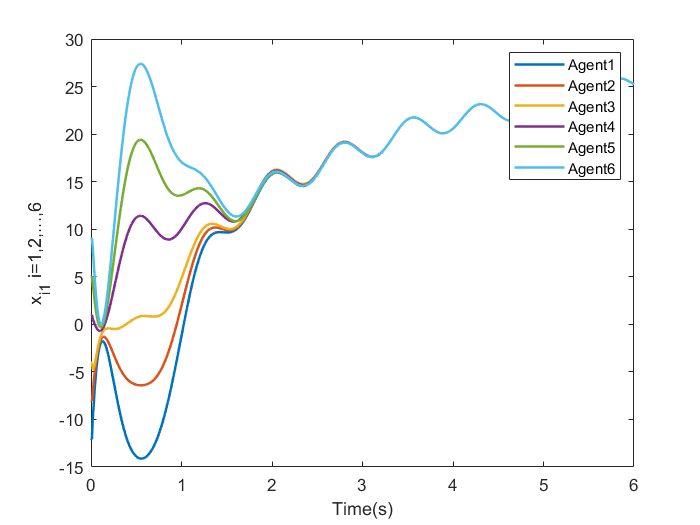

plot(t,x(1,:),t,x(5,:),t,x(9,:),t,x(13,:),t,x(17,:),t,x(21,:),'linewidth',1.5)
xlabel('Time(s)')
ylabel('x_{i1} i=1,2,...,6')
legend('Agent1','Agent2','Agent3','Agent4','Agent5','Agent6')

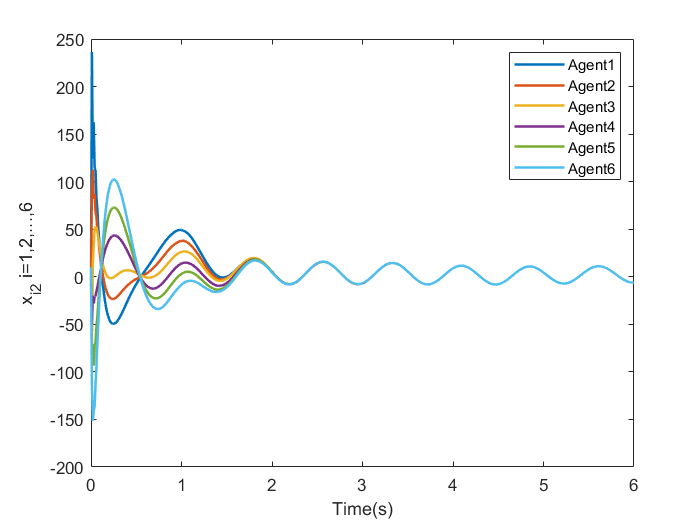

plot(t,x(2,:),t,x(6,:),t,x(10,:),t,x(14,:),t,x(18,:),t,x(22,:),'linewidth',1.5)
xlabel('Time(s)')
ylabel('x_{i2} i=1,2,...,6')
legend('Agent1','Agent2','Agent3','Agent4','Agent5','Agent6')

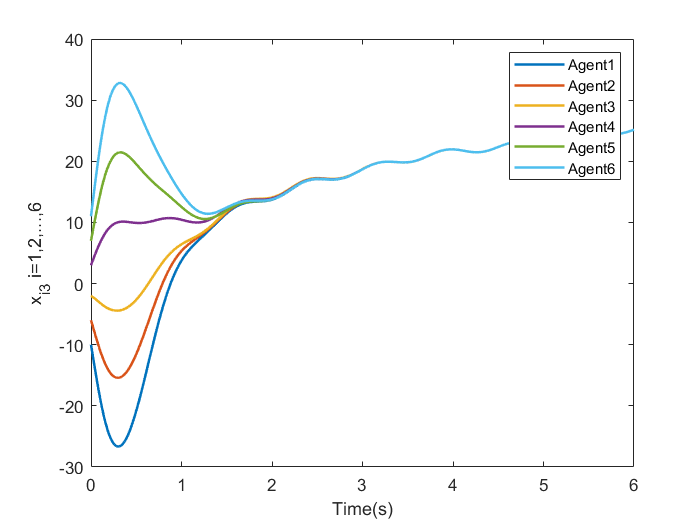

plot(t,x(3,:),t,x(7,:),t,x(11,:),t,x(15,:),t,x(19,:),t,x(23,:),'linewidth',1.5)
xlabel('Time(s)')
ylabel('x_{i3} i=1,2,...,6')
legend('Agent1','Agent2','Agent3','Agent4','Agent5','Agent6')

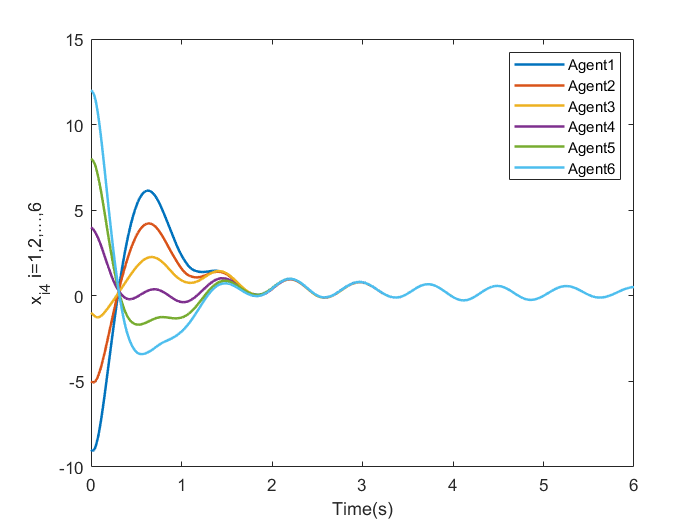

plot(t,x(4,:),t,x(8,:),t,x(12,:),t,x(16,:),t,x(20,:),t,x(24,:),'linewidth',1.5)
xlabel('Time(s)')
ylabel('x_{i4} i=1,2,...,6')
legend('Agent1','Agent2','Agent3','Agent4','Agent5','Agent6')